

% BMES 511 Group 6
% This script handles the change in cell density in response to EGF in
% corneal Epithelial Wound Healing as described in the basic model from
% Dale et Al

% Define initial conditions and constants
clear all
Dn=10^-9;
Dc=25;
k=6.31 * (10^-3);
c0= 6.6 * (10^-10);
n0=10^-12;
E0=10^-10;
delta=0.30102999566;
hc=5.75* (10^-20);
A=0.2;
alpha1=0.9;
beta1=0.1;
v=2;
u=1.37*(10^4);
initial_conditions = [n0; c0; E0];
tspan=[0 24];
c1=3.02;
E1=4;
A2=0.18;
u2=4*(10^4);
% Simulate using the differential equations using ODE45
[t, y] = ode45(@(t, y) ode_system(t, y, Dc, alpha1, beta1, v, k, u, A, delta, n0, c1,A2,E1,u2), tspan, initial_conditions);
cells= y(:,1);
EGF= y(:,2);

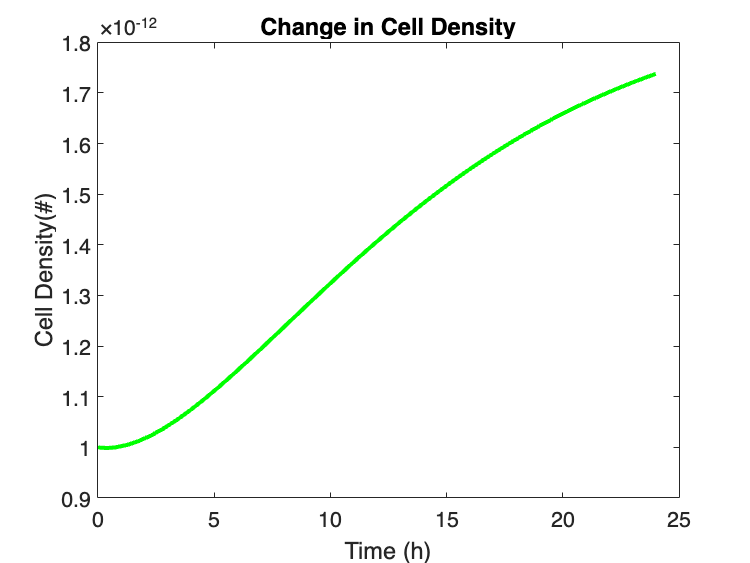

TGF= y(:,3);
% Plot the results 
plot(t,cells, 'g','LineWidth', 3)
title('Change in Cell Density','FontSize', 17);
ylabel("Cell Density(#)",'FontSize', 17);
xlabel('Time (h)','FontSize', 17);
set(gca, 'FontSize', 16);

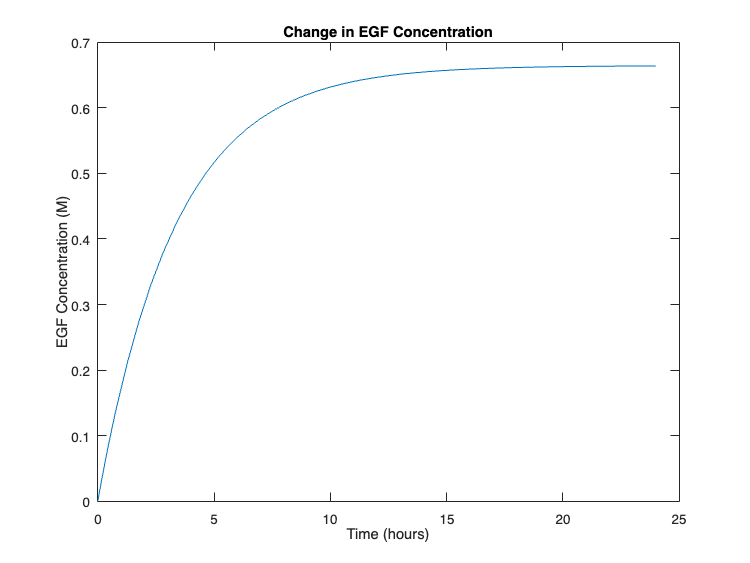

plot(t,EGF);
title('Change in EGF Concentration');
ylabel('EGF Concentration (M)');
xlabel('Time (hours)');

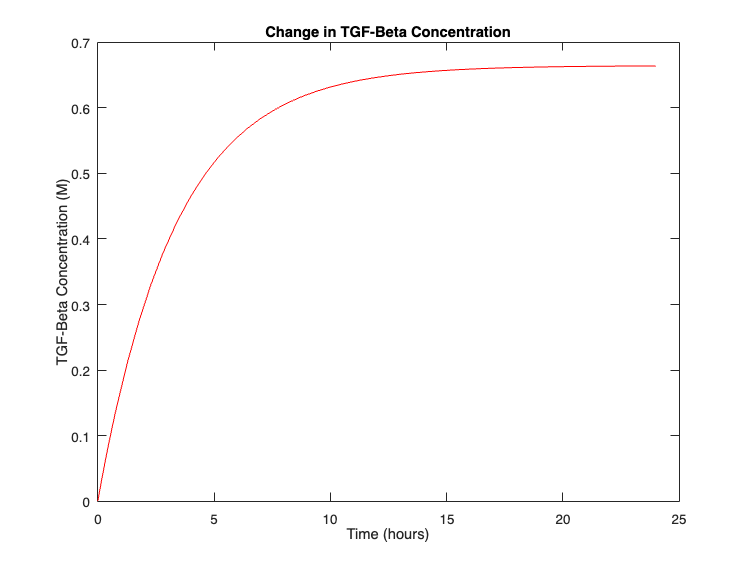

plot(t,EGF, 'r');
title('Change in TGF-Beta Concentration');
ylabel('TGF-Beta Concentration (M)');
xlabel('Time (hours)');

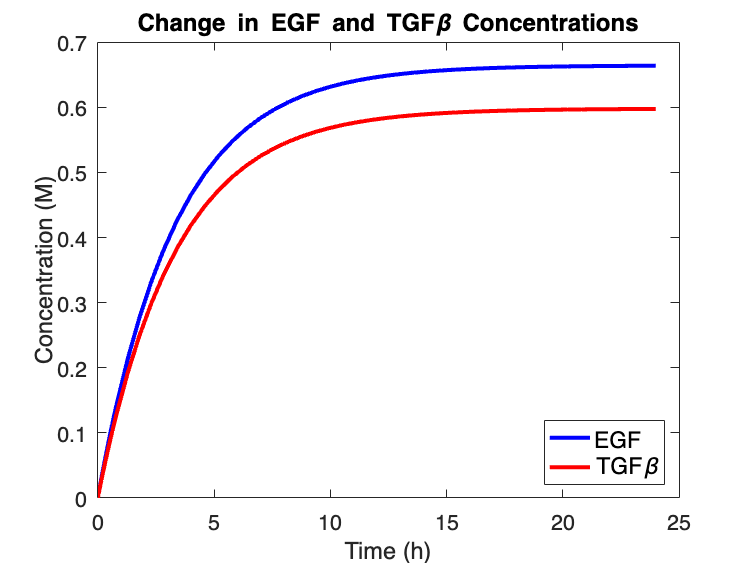


% Plot the results for EGF and TGF on the same plot
plot(t, EGF, 'b', t, TGF, 'r','LineWidth', 3);
title('Change in EGF and TGF\beta Concentrations','FontSize', 17);
ylabel('Concentration (M)','FontSize', 17);
xlabel('Time (h)','FontSize', 17);
legend('EGF', 'TGF\beta','FontSize', 17);
set(gca, 'FontSize', 16);

legend("Position", [0.72573,0.13966,0.16071,0.1131])

cells_vec=[];
EGF_vec=[];
TGF_vec=[];
x=0;
for i=0:0.02:0.30
    [t, y] = ode45(@(t, y) ode_system(t, y, Dc, alpha1, beta1, v, k, u, A, delta, n0, c1,i,E1,u2), tspan, initial_conditions);
    x=x+1;
    cells_vec(:,x)= y(:,1);
    EGF_vec(:,x)= y(:,2);
    TGF_vec(:,x)= y(:,3);
end

inflows=0:0.02:0.30;
[T,Z]=meshgrid(t,inflows);
disp(size(cells_vec));

    61    16



disp(size(T));

    16    61



disp(size(Z));

    16    61



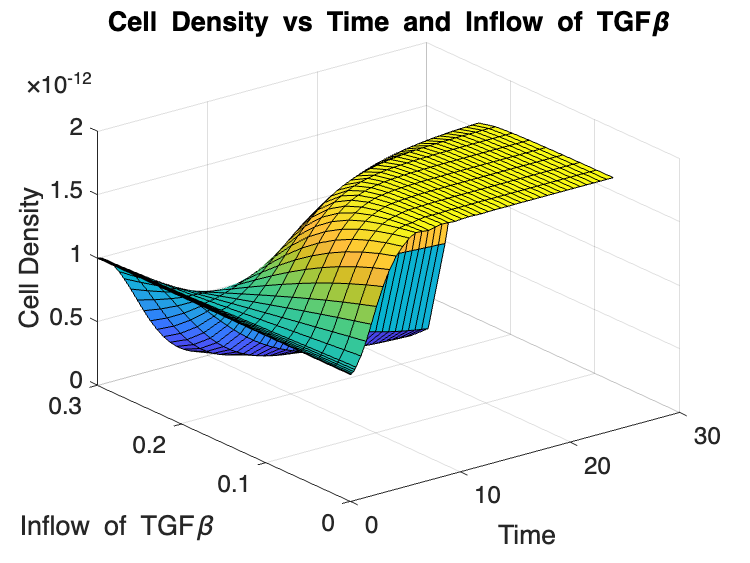

surf(T',Z', cells_vec);
xlabel('Time');
ylabel('Inflow of TGF\beta');
zlabel('Cell Density');
title('Cell Density vs Time and Inflow of TGF\beta');
set(gca, 'FontSize', 18);

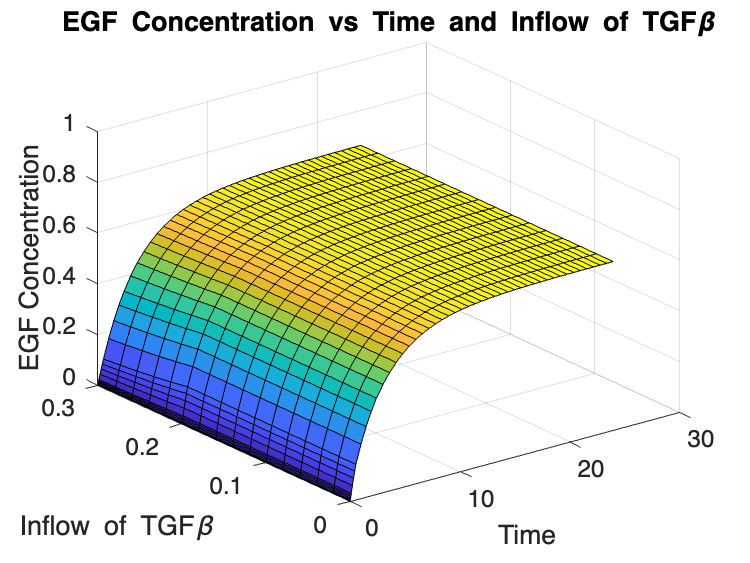


surf(T',Z', EGF_vec);
xlabel('Time');
ylabel('Inflow of TGF\beta');
zlabel('EGF Concentration');
title('EGF Concentration vs Time and Inflow of TGF\beta');
zlim([0 1]);
set(gca, 'FontSize', 18);

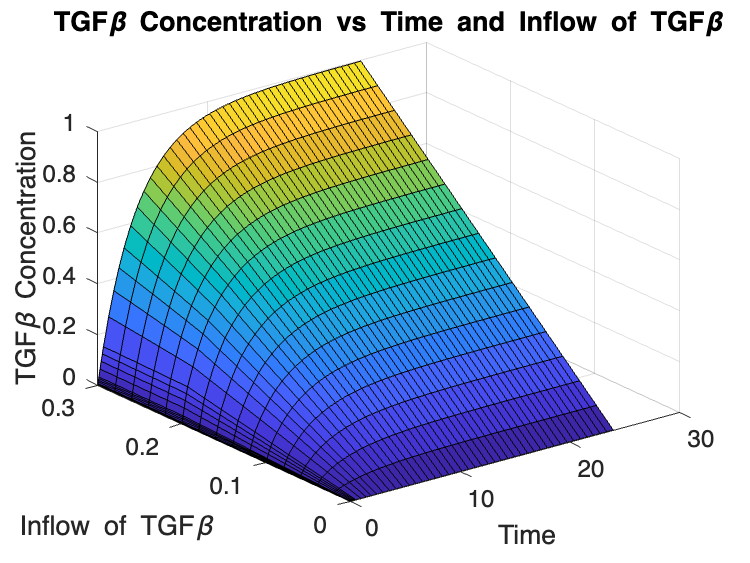

surf(T',Z', TGF_vec);
xlabel('Time');
ylabel('Inflow of TGF\beta');
zlabel('TGF\beta Concentration');
title('TGF\beta Concentration vs Time and Inflow of TGF\beta');
set(gca, 'FontSize', 18);